warning off
init_deconvolution


Adding toolboxes and subfolders to path...

projectFolder = /net/store/nbp/users/behinger/projects/deconvolution/git


Adding toolboxes and subfolders to path... 


warning onW

# Introduction

Subjects are exploring a face stimulus. Using an eyetracker and the EEG-Eye toolbox we add markers of saccade onsets into our EEG-Data. The data were cleaned for eye-movement related artefacts using ICA.

In this tutorial we try to disentangle stimulus related ERPs and microsaccade related ERPs.

PROJECTPATH = '/media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/';
EEG = pop_loadset('filename','msaff_15.set','filepath',sprintf('%s/02_sync_data_with_sacc',PROJECTPATH));

pop_loadset(): loading file /media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/02_sync_data_with_sacc/msaff_15.set ...


EEG = eeg_checkset(EEG);

# Defining the design

cfgDesign = [];
% Notice how we can group multiple stimuli into a single event
cfgDesign.eventtype = {'saccade',{'S121','S122','S123'}};
% We use intercept-only formulas because we are only interested in the overlap for now
cfgDesign.formula = {'y ~ 1','y~1'};
EEG = uf_designmat(EEG,cfgDesign);

Multiple events with separate model-formula detected


Modeling event(s) [saccade] using formula: y ~ 1 
Modeling event(s) [S121,S122,S123] using formula: y~1 


# Timeshift

In order to compensate for the inevitable linear overlap between ERPs, we want to use timeshifting / prepare the designmatrix for the deconvolution step. In this step we generate for each column of the designmatrix timeshifted (by t = 1, t=2, t=3 ...) and append them to the designmatrix.

cfgTimeexpand = [];
cfgTimeexpand.timelimits = [-.3,0.8];

EEG = uf_timeexpandDesignmat(EEG,cfgTimeexpand);


dc_timeexpandDesignmat(): Timeexpanding the designmatrix...
...done


# Cleaning of data

% A simple threshold function taken from ERPLAB
winrej = uf_continuousArtifactDetect(EEG,'amplitudeThreshold',250);


	So, basicrap.m will be applied over the full range of data.

Please wait. This might take several seconds...

 91 segments were marked.



% We remove very noisy data segments (>250mV) from the designmatrix
EEG = uf_continuousArtifactExclude(EEG,struct('winrej',winrej));


removing 11.5% from design matrix (fill it with zeros) 


# Fit the deconvolution model

EEG= uf_glmfit(EEG,'channel',[32]);


dc_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 32 (of 1 electrodes in total)... 19 iterations, took 1.4s
 LMfit finished 


# Fit the non-deconvolution model

While epoching changes the *EEG.data*, the previous *EEG.deconv* fields & fits do not. Thus the toolbox allows to have two fits, a "dc beta" and a "no-dc beta" concurrently

% We need to provide the same winrej as before, so that approximately the same data is used for the model. 
% Only approximately because in epoched data we need to remove a whole trial, whereas deconvolution allows
% partial trial-data to be used.

% Be aware that if you decide to overwrite the EEG structure you need to reload your data to rerun your analysis on continuous data
EEG = uf_epoch(EEG,struct('winrej',winrej,'timelimits',cfgTimeexpand.timelimits));

Deleting 320 events due to data cleaning 
pop_epoch():1831 epochs selected
Epoching...
pop_epoch():1831 epochs generated
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 


EEG = uf_glmfit_nodc(EEG); 

# Plot the results

We choose a single electrode and plot all effects.

ufresult= uf_condense(EEG);
display(ufresult)

unfold =        deconv: [1×1 struct]
         beta: [48×550×2 double]
        times: [1×550 double]
     chanlocs: [1×48 struct]
        param: [1×2 struct]
    beta_nodc: [48×550×2 double]


plotting all parameters


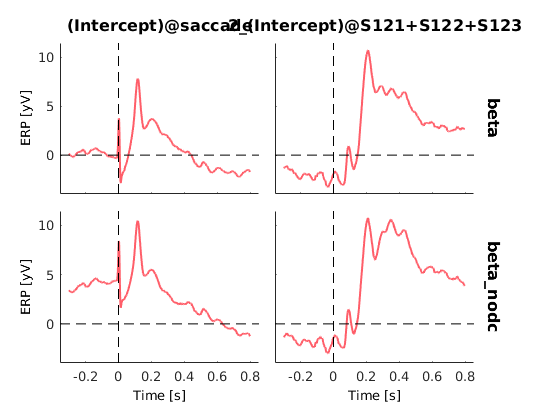

uf_plotParam(ufresult,'channel',32);

In order to directly compare the dc and non-dc model fits we can plot them in the same plot. Not the large baseline offset (no baseline correction so far) that is completly absent in the deconvoluted fit (this is an observeration we commonly have in many different datasets). For the comparison we do want to have baseline correction.

%first plot the deconvoluted betas
g = uf_plotParam(ufresult,'channel',32,'deconv',1,'baseline',[unfold.times(1) 0]);

plotting all parameters


performing baseline correction 


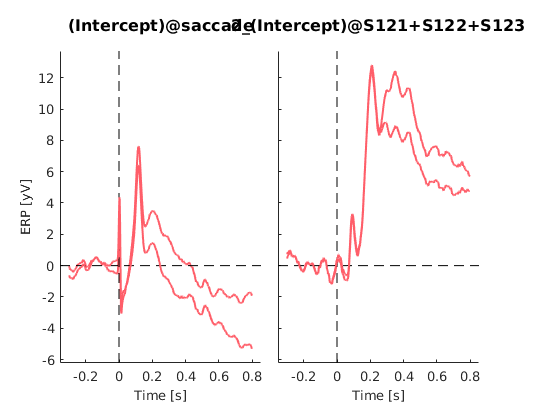

plotting all parameters


performing baseline correction 
New X or Y of different size given, all data from first gramm cleared


% now plot the non-deconvoluted betas
g = uf_plotParam(ufresult,'channel',32,'deconv',0,'baseline',[unfold.times(1) 0],'gramm',g);

It is clear that disregarding the overlap leads to vastly different results for late components, but obviously not for early components, as no overlap happened here.